**Derivatives**

- Slope of lines on a graph

- How y is changing as x changes (with respect to x)

- dy/dx = deltay/deltax

- diff() takes in a vector of numbers, starting at the second element, it finds the difference between each number and the one before it

- gives back one fewer element

- v = [2 4 8]

- [ v(2)-v(1),  v(3)-v(2) ] = diff(v)

- Analytical Derivative (power rule)

- 2*x^2 + 4*x + 5 ---> 4*x + 4

- coefficients = [2 4 5]

- powers = [2 1 0]

- derivCoefficients = coefficients .* powers = [2 4 5] .* [2 1 0] = [4 4 0]

- Must remove last term to reduce order by one --> [4 4]

diff()

vec = [ 1 3 6 12 20 34 40 45 ]

vec =      1     3     6    12    20    34    40    45


dv = diff(vec)

dv =      2     3     6     8    14     6     5


Linear

figure
hold on
grid on

%Plot original data
x = -5:5

x =     -5    -4    -3    -2    -1     0     1     2     3     4     5


y = 2.*x

y =    -10    -8    -6    -4    -2     0     2     4     6     8    10


plot(x,y,'r','linewidth',6) 

%Numerical Derivative
dx = diff(x)

dx =      1     1     1     1     1     1     1     1     1     1


dy = diff(y)

dy =      2     2     2     2     2     2     2     2     2     2


first = dy ./ dx

first =      2     2     2     2     2     2     2     2     2     2


plot(x(1:end-1)+.5,first,'g','linewidth',6) 

%Analytical Derivative (Power Rule)
coeffs = [2 0]

coeffs =      2     0


pow = length(coeffs)-1 : -1 : 0

pow =      1     0


derivCoeffs = coeffs .* pow

derivCoeffs =      2     0


derivCoeffs(end) = []

derivCoeffs = 2

derivy = polyval(derivCoeffs, x)

derivy =      2     2     2     2     2     2     2     2     2     2     2


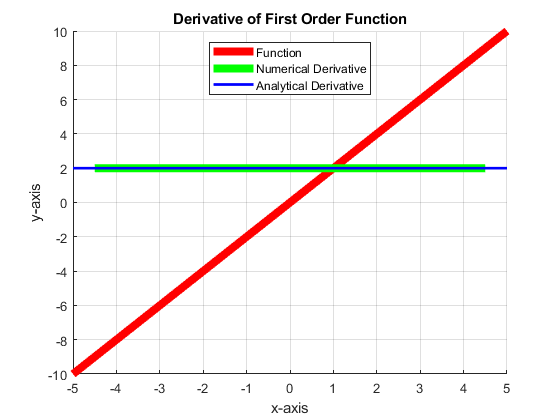

plot(x,derivy,'b','linewidth',2)

%Annotaions
title('Derivative of First Order Function')
xlabel('x-axis')
ylabel('y-axis')
legend('Function','Numerical Derivative','Analytical Derivative', 'location','north')

Parabola

figure
hold on
grid on

%Plot original data
x = -5:5

x =     -5    -4    -3    -2    -1     0     1     2     3     4     5


y = x.^2

y =     25    16     9     4     1     0     1     4     9    16    25


plot(x,y,'r','linewidth',6) 

%Numerical Derivative
dx = diff(x)

dx =      1     1     1     1     1     1     1     1     1     1


dy = diff(y)

dy =     -9    -7    -5    -3    -1     1     3     5     7     9


first = dy ./ dx

first =     -9    -7    -5    -3    -1     1     3     5     7     9


plot(x(1:end-1)+.5,first,'g','linewidth',6)

%Analytical Derivative (Power Rule)
coeffs = [1 0 0]

coeffs =      1     0     0


pow = length(coeffs)-1 : -1 : 0

pow =      2     1     0


derivCoeffs = coeffs .* pow

derivCoeffs =      2     0     0


derivCoeffs(end) = []

derivCoeffs =      2     0


derivy = polyval(derivCoeffs, x)

derivy =    -10    -8    -6    -4    -2     0     2     4     6     8    10


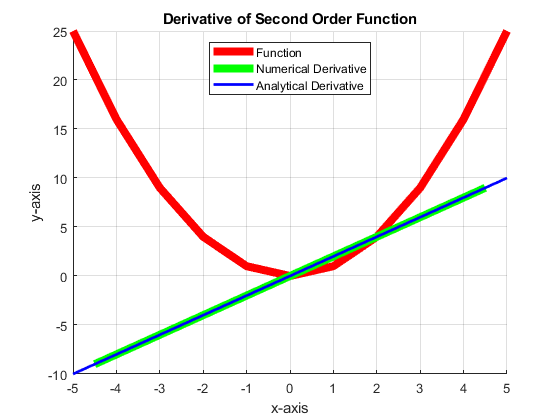

plot(x,derivy,'b','linewidth',2)

%Annotaions
title('Derivative of Second Order Function')
xlabel('x-axis')
ylabel('y-axis')
legend('Function','Numerical Derivative','Analytical Derivative', 'location','north')

Third Order Function

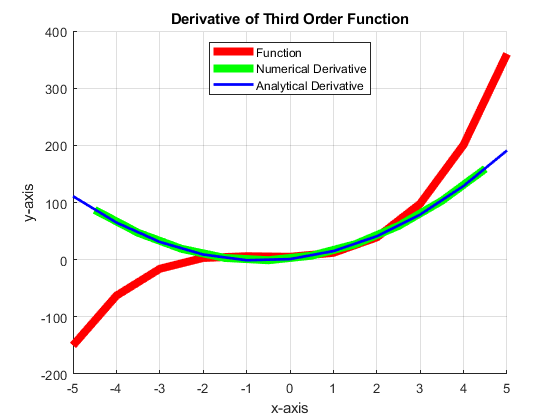

figure
hold on
grid on

x = -5:5;
y = 2*x.^3 + 4*x.^2 + x + 5;
plot(x,y,'r','linewidth',6) 

%Numerical Derivative
dx = diff(x);
dy = diff(y);
first = dy ./ dx;
plot(x(1:end-1)+.5,first,'g','linewidth',6)

%Analytical Derivative (Power Rule)
coeffs = [2 4 1 5];
pow = length(coeffs)-1 : -1 : 0;
derivCoeffs = coeffs .* pow;
derivCoeffs(end) = [];
derivy = polyval(derivCoeffs, x);
plot(x,derivy,'b','linewidth',2)

%Annotaions
title('Derivative of Third Order Function')
xlabel('x-axis')
ylabel('y-axis')
legend('Function','Numerical Derivative','Analytical Derivative', 'location','north')

Fourth Order Function

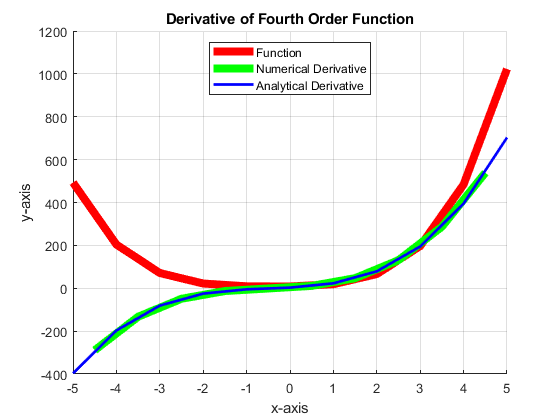

figure
hold on
grid on

x = -5:5;
y = x.^4 + 2*x.^3 + 5*x.^2 + 3*x + 8;  
plot(x,y,'r','linewidth',6) 

%Numerical Derivative
dx = diff(x);
dy = diff(y);
first = dy ./ dx;
plot(x(1:end-1)+.5,first,'g','linewidth',6)

%Analytical Derivative (Power Rule)
coeffs = [1 2 5 3 8];
pow = length(coeffs)-1 : -1 : 0;
derivCoeffs = coeffs .* pow;
derivCoeffs(end) = [];
derivy = polyval(derivCoeffs, x);
plot(x,derivy,'b','linewidth',2)

%Annotaions
title('Derivative of Fourth Order Function')
xlabel('x-axis')
ylabel('y-axis')
legend('Function','Numerical Derivative','Analytical Derivative', 'location','north')